## Path Planning of Capsule Robot

Plan the path of a capsule robot having the below given dimensions to navigate from the trachea to the narrow tip of the airway.

Length of capsule = 10 mm

Diameter of capsule = 5 mm

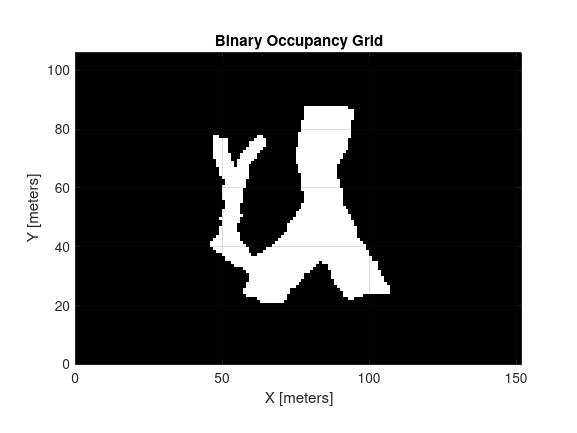

img = imresize(imcomplement(imbinarize(rgb2gray(imread('airway_img.png')))),0.115);
binary_map = binaryOccupancyMap(img);
show(binary_map);
grid on;

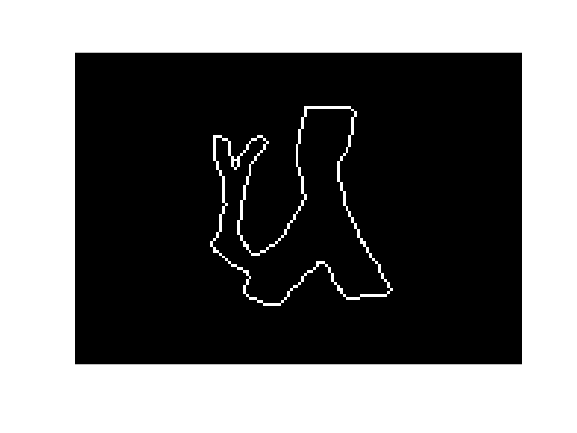

new_img = edge(img,'Sobel');
imshow(new_img)

### RRT planner 

init_state_space = stateSpaceSE2;
state_validator = validatorOccupancyMap(init_state_space);
state_validator.Map = binary_map;
state_validator.ValidationDistance = 0.25;
init_state_space.StateBounds = [ binary_map.XWorldLimits;binary_map.YWorldLimits; [-pi pi]];
planner = plannerRRT(init_state_space,state_validator);
planner.MaxConnectionDistance = 0.45;
planner.MaxIterations = 5e4;

Middle of trachea start point

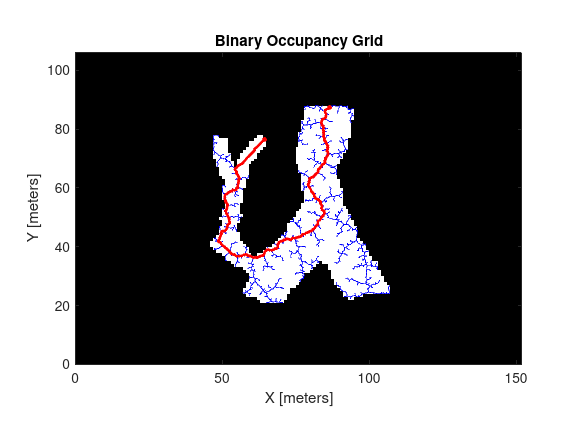

start = [86.5,87.5,0];
goal = [64.5,76.5,0];
[pathObj, sol]=plan(planner,start,goal);
show(binary_map);
hold on
plot(sol.TreeData(:,1),sol.TreeData(:,2),'b-');
plot(pathObj.States(:,1),pathObj.States(:,2),'r-','LineWidth',2);
plot(start(1),start(2),'ro',goal(1),goal(2),'ro','MarkerSize',3,'MarkerFaceColor','r');
hold off

Show the states as [ x , y , theta ] where theta is the orientation angle in radians

pathObj.States

ans =    86.5000   87.5000         0
   86.2700   87.1133    0.0199
   85.8714   86.9045    0.0349
   85.5296   86.6118    0.0194
   85.0896   86.5176    0.0281
   84.9703   86.0837    0.0232
   85.0047   85.6351   -0.0030
   85.3324   85.3267   -0.0041
   85.2674   84.8814   -0.0241
   85.2847   84.4318   -0.0271


Left end of trachea start point

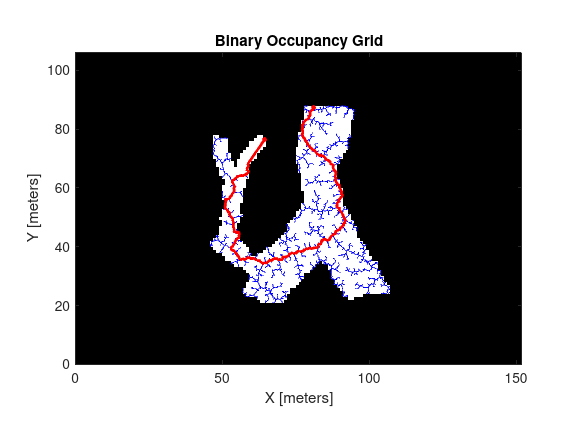

start = [81,87.5,0];
goal = [64.5,76.5,0];
[pathObj, sol]=plan(planner,start,goal);
show(binary_map);
hold on
plot(sol.TreeData(:,1),sol.TreeData(:,2),'b-');
plot(pathObj.States(:,1),pathObj.States(:,2),'r-','LineWidth',2);
plot(start(1),start(2),'ro',goal(1),goal(2),'ro','MarkerSize',3,'MarkerFaceColor','r');
hold off

Right end of trachea

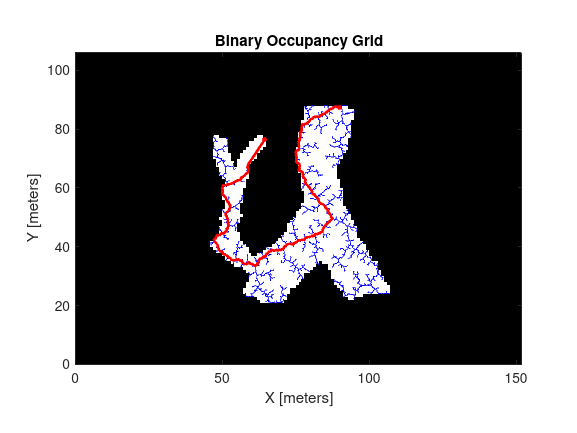

start = [90,87.5,0];
goal = [64.5,76.5,0];
[pathObj, sol]=plan(planner,start,goal);
show(binary_map);
hold on
plot(sol.TreeData(:,1),sol.TreeData(:,2),'b-');
plot(pathObj.States(:,1),pathObj.States(:,2),'r-','LineWidth',2);
plot(start(1),start(2),'ro',goal(1),goal(2),'ro','MarkerSize',3,'MarkerFaceColor','r');
hold off

Map x,y and theta for given start and goal

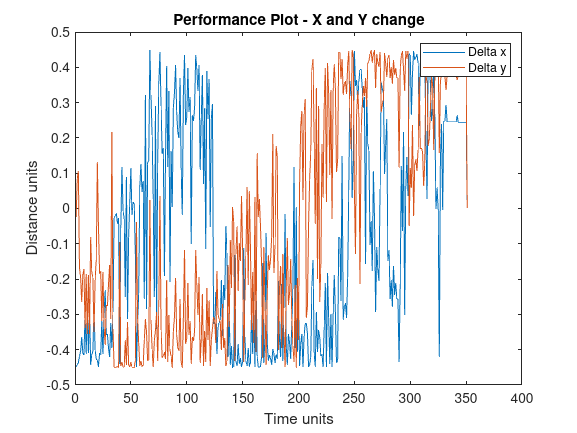

del_x = zeros(length(pathObj.States)-1,1);
del_y = zeros(length(pathObj.States)-1,1);
del_theta = zeros(length(pathObj.States)-1,1);
for i=(2:length(pathObj.States)-1)
    del_x(i-1) = pathObj.States(i,1)-pathObj.States(i-1,1);
    del_y(i-1) = pathObj.States(i,2)-pathObj.States(i-1,2);
    del_theta(i-1) = atand(del_y(i-1)/del_x(i-1));
end
%%
figure
plot(del_x);
hold on
plot(del_y);
title("Performance Plot - X and Y change");
xlabel("Time units");
ylabel("Distance units");
legend('Delta x', 'Delta y');
hold off

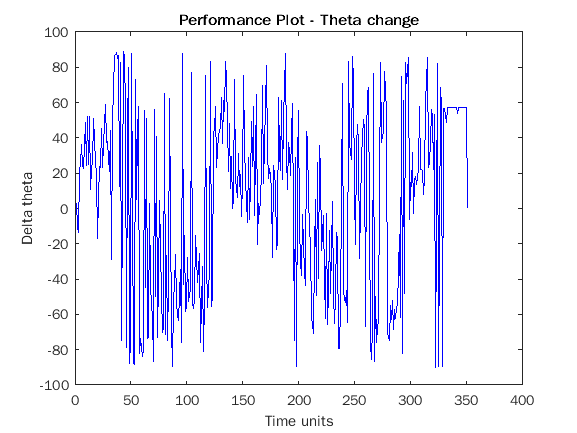

figure
plot(del_theta,'b');
title("Performance Plot - Theta change");
xlabel("Time units");
ylabel("Delta theta");

## Getting a reference path

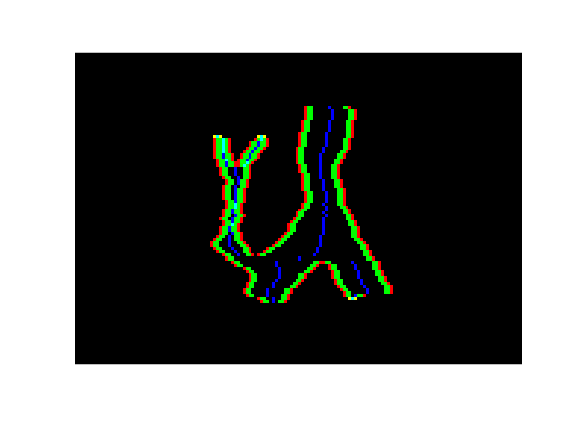

current_state = true;
edges = [];
count = 0 ;
path = [];
heuristic_map=zeros(106,152,3);
for row = [15:90]
    for col = [35:120]
        if img(row,col) ~= current_state
            edges = [edges ; row col];
            current_state = ~ current_state;
            count= count+1;
            heuristic_map(row,col,1)=50;
            for i = [1:2]
                if count==1
                    heuristic_map(row,col+i,2)=100;
                else
                    heuristic_map(row,col-i,2)=100;
                end
            end
        end
        if (count ==2 )
            c1 = edges(end-1,2);
            c2 = edges(end,2);
            path = [path ; row (c2+c1)*0.5];
            heuristic_map(row, uint8((c2+c1)*0.5),3)=200;
            count=0;
        
        end
    end
    count = 0 ;
end
imshow(heuristic_map)

Ideal path 

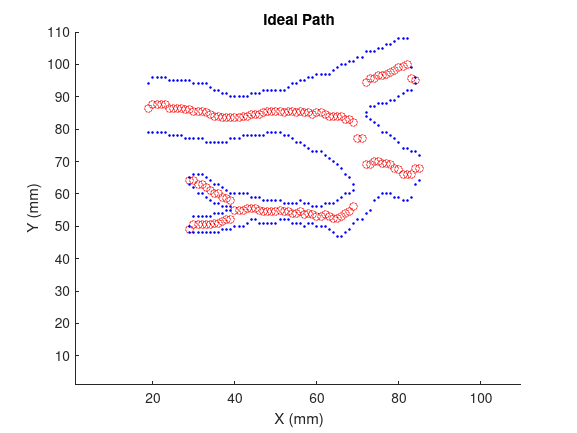

figure
scatter(path(:,1),path(:,2),30,'ro')
hold on
scatter(edges(:,1),edges(:,2),30,'b.')
xlim([1,110])
ylim([1,110])
title('Ideal Path')
xlabel("X (mm)")
ylabel("Y (mm)")
hold off